# Simulation Of Ground Acceleration Record

Time series of acceleration records are simulated using a stationary process that is "weighted" by an envelope function. The function that fulfils this procedure is 'seismSim'. The parameters of the simulated seismic record are retrieved using the function 'fitKT'

## Ground acceleration record computation

%frequency vector
f = linspace(0,48,4096);

- select `bandwidth of the earthquake excitation`

zeta = 0.3;

- select the standard deviation of `earthquake excitation`

sigma = 0.35;

- select `dominant frequency of the earthquake excitation (Hz).`

fn = 10;

- select `value of the envelop function at 90 percent of the duration.`

T90 = 0.25;

- select `normalized duration time when ground motion achieves peak.`

eps = 0.4;

- **select **duration of ground motion;

tn = 60;

Calling this function

% function call
[y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn); 
% y: acceleration record
% t: time

### Plot Function

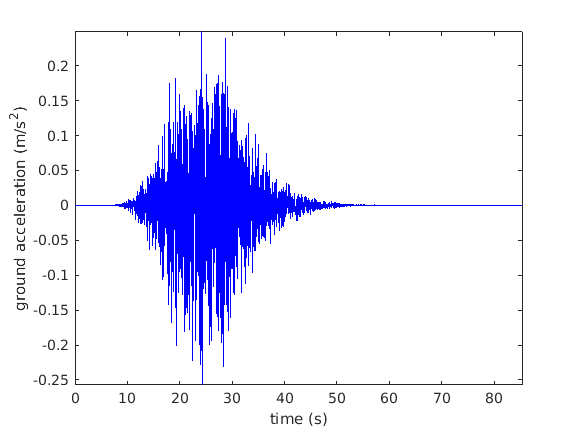

plot(t,y,'b');
xlabel('time (s)')
ylabel('ground acceleration (m/s^2)')
axis tight

Earthquake data has been generated.

set(gcf,'color','w');

**A Moving Average Filter**

In its simplest form, a moving average filter of length N takes the average of every N consecutive samples of the waveform.

To apply a moving average filter to each data point, we construct our coefficients of our filter so that each point is equally weighted and contributes 1/24 to the total average. This gives us the average acceleration over each 24 data point.

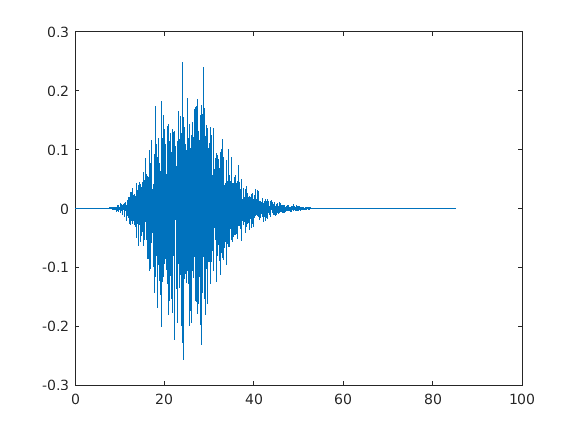

timewindow = 24;
coeff24hMA = ones(1, timewindow)/timewindow;

avg_acc = filter(coeff24hMA, 1, y);
plot(t,y)

plot(t,avg_acc)
legend('Acceleration ','weighted time (delayed)','location','best')

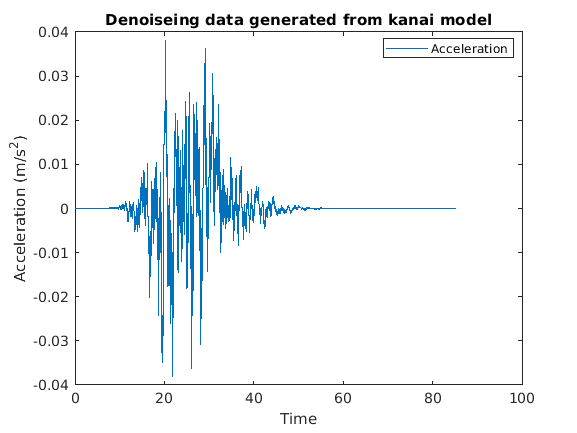

ylabel('Acceleration (m/s^2)')
xlabel('Time')
title('Denoiseing data generated from kanai model')

**Extracting Average Differences**

Alternatively, we can also use the moving average filter to obtain a better estimate of how the time  affects the overall acceleration. To do this, first, subtract the smoothed data from the  measurements. Then, segment the differenced data into time windows and take the average over all slides.

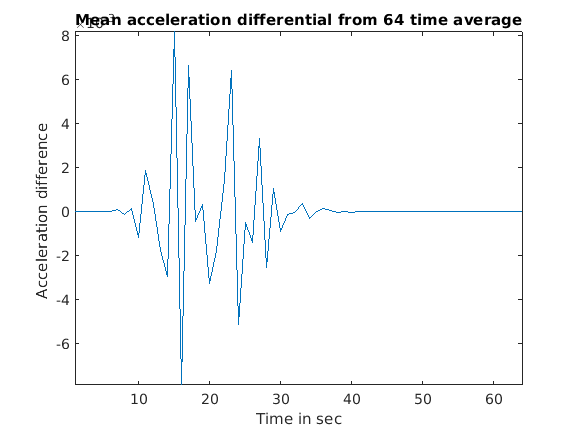

figure
deltaAccel = y - avg_acc;
deltaAccel = reshape(deltaAccel,64,64);


plot(1:64, mean(deltaAccel))
axis tight
title('Mean acceleration differential from 64 time average')
xlabel('Time in sec')
ylabel('Acceleration difference ')

**Extracting Peak Envelope**

Sometimes we would also like to have a smoothly varying estimate of how the highs and lows of our  signal change overtime. To do this we can use the `envelope` function to connect extreme highs and lows detected over a subset of the time. In this example, we ensure there are at least 16 time between each extreme high and extreme low. We can also get a sense of how the highs and lows are trending by taking the average between the two extremes.

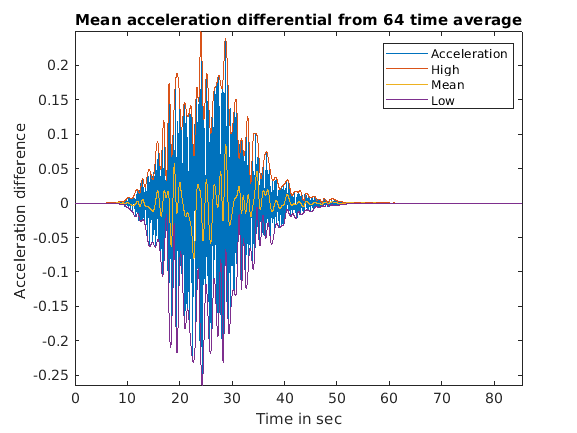

[envHigh, envLow] = envelope(y,16,'peak');
envMean = (envHigh+envLow)/2;

plot(t,y, ...
     t,envHigh, ...
     t,envMean, ...
     t,envLow)
axis tight
legend('Acceleration','High','Mean','Low','location','best')
title('Mean acceleration differential from 64 time average')
xlabel('Time in sec')
ylabel('Acceleration difference ')

**Weighted Moving Average Filters**

Other kinds of moving average filters do not weight each sample equally.

Another common filter follows the binomial expansion of [1/2,1/2]*n*. This type of filter approximates a normal curve for large values of n. It is useful for filtering out high frequency noise for small n. To find the coefficients for the binomial filter, convolve [1/2,1/2] with itself and then iteratively convolve the output with [1/2,1/2] a prescribed number of times. In this example, use five total iterations.

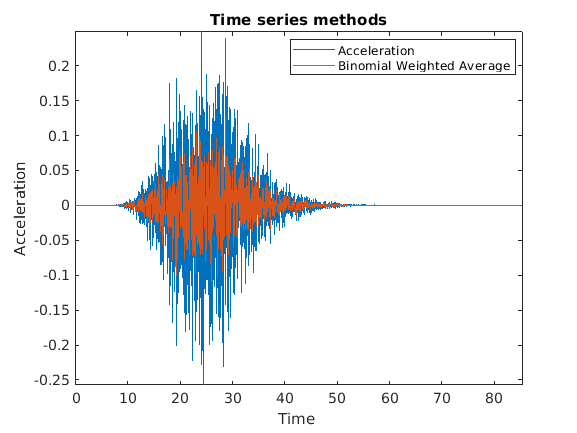

h = [1/2 1/2];
binomialCoeff = conv(h,h);
for n = 1:4
    binomialCoeff = conv(binomialCoeff,h);
end

figure
fDelay = (length(binomialCoeff)-1)/2;
binomialMA = filter(binomialCoeff, 1, y);
plot(t,y, ...
     t-fDelay/24,binomialMA)
axis tight
legend('Acceleration','Binomial Weighted Average','location','best')
ylabel('Acceleration')
xlabel('Time ')
title('Time series methods')

## Fitting the ground acceleratoin record to target spectra & envelop

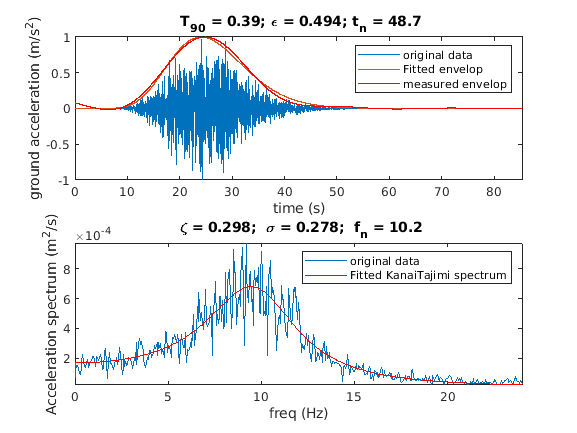

guessEnvelop=[0.33,0.43,50]; % guest for envelop 
guessKT = [1,1,5]; % guess for spectrum
[T90,eps,tn,zeta,sigma,fn] = fitKT(t,y,guessEnvelop,guessKT,...
    'dataPlot','yes');

#### Simulation Function:

function [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn)
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn) generate one time series
% corresponding to acceleration record from a seismometer. The function
% requires 7 inputs, and gives 2 outputs. The time series is generated in
% two steps: First a stationnary process is created based on the Kanai-
% Tajimi spectrum, then an envelope function is used to transform this 
% stationnary time series into a non-stationary record. For more
% information, see [1-3].
% [1] Lin, Y. K., & Yong, Y. (1987). Evolutionary Kanai-Tajimi earthquake
% models. Journal of engineering mechanics, 113(8), 1119-1137.
% [2] Rofooei, F. R., Mobarake, A., & Ahmadi, G. (2001). 
% Generation of artificial earthquake records with a nonstationary 
% KanaiTajimi model. Engineering Structures, 23(7), 827-837.
% [3] Guo, Y., & Kareem, A. (2016). 
% System identification through nonstationary data using TimeFrequency Blind
% Source Separation. Journal of Sound and Vibration, 371, 110-131.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: standard deviation of the excitation.
% fn: [1 x 1 ]: dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]:  bandwidth of the earthquake excitation.
% f: [ 1 x M ]: frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: value at 90 percent of the duration.
% eps: [1 x 1 ]: normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : Simulated aceleration record
% t: size: [ 1 x N ] : time
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.9;
% fn =5;
% T90 = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,T90,eps,tn);
% figure
% plot(t,y);axis tight
% xlabel('time(s)');
% ylabel('ground acceleration (m/s^2)')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also fitKT.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% Initialisation
w = 2*pi.*f;
fs = f(end); dt = 1/fs;
f0= median(diff(f));
Nfreq = numel(f);
t = 0:dt:dt*(Nfreq-1);

%% Generation of the spectrum S
fn = fn *2*pi; % transformation in rad;
s0 = 2*zeta*sigma.^2./(pi.*fn.*(4*zeta.^2+1));
A = fn.^4+(2*zeta*fn*w).^2;
B = (fn.^2-w.^2).^2+(2*zeta*fn.*w).^2;
S = s0.*A./B; % single sided PSD


%% Time series generation - Monte Carlo simulation
A = sqrt(2.*S.*f0);
B =cos(w'*t + 2*pi.*repmat(rand(Nfreq,1),[1,Nfreq]));
x = A*B; % stationary process

%% Envelop function E
b = -eps.*log(T90)./(1+eps.*(log(T90)-1));
c = b./eps;
a = (exp(1)./eps).^b;
E = a.*(t./tn).^b.*exp(-c.*t./tn);

%% Envelop multiplied with stationary process to get y
y = x.*E;

end

### FitKT function

function [T90,eps,tn,zeta,sigma,fn] = fitKT(t,y,guessEnvelop,guessKT,varargin)
% [T90,eps,tn,zeta,sigma,fn] = fitKT(t,y,fs,guessEnvelop,guessKT,
% varargin) fit the nonstationary KanaiTajimi model to ground acceleration
% records. 
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% INPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% y: size: [ 1 x N ] : aceleration record
% t: size: [ 1 x N ] : time vector
% guessEnvelop: [1 x 3 ]: first guess for envelop function
% guessKT: [1 x 3 ]: first guess for KanaiTajimi spectrum
% varargin:
%      'F3DB'        - cut off frequency for the low pass filter
%      'TolFun'      - Termination tolerance on the residual sum of squares.
%                      Defaults to 1e-8.
%      'TolX'        - Termination tolerance on the estimated coefficients
%                      BETA.  Defaults to 1e-8.
%      'dataPlot'        - 'yes': show the results of the fitting process
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% OUTPUTS 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% sigma: [1 x 1 ]: Fitted standard deviation of the excitation.
% fn: [1 x 1 ]:  Fitted dominant frequency of the earthquake excitation (Hz).
% zeta: [1 x 1 ]: Fitted bandwidth of the earthquake excitation.
% f: [ 1 x M ]: Fitted frequency vector for the Kanai-tajimi spectrum.
% T90: [1 x 1 ]: Fitted value at 90 percent of the duration.
% eps: [1 x 1 ]: Fitted normalized duration time when ground motion achieves peak.
% tn: [1 x 1 ]: Fitted duration of ground motion.
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% EXAMPLE: this requires the function seismSim.m
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
% f = linspace(0,40,2048);
% zeta = 0.3;
% sigma = 0.3;
% fn =5;
% eta = 0.3;
% eps = 0.4;
% tn = 30;
% [y,t] = seismSim(sigma,fn,zeta,f,eta,eps,tn);
% guessEnvelop=[0.33,0.43,50];
% guessKT = [1,1,5];
% [eta,eps,tn,zeta,sigma,fn] = fitKT(t,y,guessEnvelop,guessKT,...
% 'dataPlot','yes');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% see also seismSim.m
% Author: Etienne Cheynet - modified: 23/04/2016

%% inputParser
p = inputParser();
p.CaseSensitive = false;
p.addOptional('f3DB',0.05);
p.addOptional('tolX',1e-8);
p.addOptional('tolFun',1e-8);
p.addOptional('dataPlot','no');
p.parse(varargin{:});
tolX = p.Results.tolX ;
tolFun = p.Results.tolFun ;
f3DB = p.Results.f3DB ;
dataPlot = p.Results.dataPlot ;
% check number of input
narginchk(4,8)

%% Get envelop parameters
dt = median(diff(t));

h1=fdesign.lowpass('N,F3dB',8,f3DB,1/dt);
d1 = design(h1,'butter');
Y = filtfilt(d1.sosMatrix,d1.ScaleValues, abs(hilbert(y)));
Y = Y./max(abs(Y));

options=optimset('Display','off','TolX',tolX,'TolFun',tolFun);
coeff1 = lsqcurvefit(@(para,t) Envelop(para,t),guessEnvelop,t,Y,[0.01,0.01,0.1],[3,3,100],options);

eps = coeff1(1);
T90 = coeff1(2);
tn = coeff1(3);





%% Get stationnary perameters for the spectrum
E =Envelop(coeff1,t);
x = y./E; % there may be better solution than this one, but I don't have better idea right now.
x(1)=0;

% calculate the PSD
[PSD,freq]=pwelch(x,[],[],[],1/median(diff(t)));%%
coeff2 = lsqcurvefit(@(para,t) KT(para,freq),guessKT,freq,PSD,[0.01,0.01,1],[5,5,100],options);
zeta = coeff2(1);
sigma = coeff2(2);
fn = coeff2(3);



%% dataPLot (optional)
if strcmpi(dataPlot,'yes'),
    spectra = KT(coeff2,freq);
    
    figure
    subplot(211)
    plot(t,y./max(abs(y)),t,Envelop(coeff1,t),t,Y,'r')
    legend('original data','Fitted envelop','measured envelop')
    title([' T_{90} = ',num2str(coeff1(2),3),'; \epsilon = ',...
        num2str(coeff1(1),3),'; t_{n} = ',num2str(coeff1(3),3)]);
    xlabel('time (s)')
    ylabel('ground acceleration (m/s^2)')
    axis tight
    
    subplot(212)
    plot(freq,PSD,freq,spectra,'r')
    legend('Measured','Fitted envelop')
    legend('original data','Fitted KanaiTajimi spectrum')
    title([' \zeta = ',num2str(coeff2(1),3),';  \sigma = ',...
        num2str(coeff2(2),3),';  f_{n} = ',num2str(coeff2(3),3)]);
    xlabel('freq (Hz)')
    ylabel('Acceleration spectrum (m^2/s)')
    axis tight
    set(gcf,'color','w')
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% NESTED FUNCTIONS
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    function E = Envelop(para,t)
        eps0 = para(1);
        eta0 = para(2);
        tn0 = para(3);
        b = -eps0.*log(eta0)./(1+eps0.*(log(eta0)-1));
        c = b./eps0;
        a = (exp(1)./eps0).^b;
        E = a.*(t./tn0).^b.*exp(-c.*t./tn0);
    end
    function S = KT(para,freq)
        zeta0 = para(1);
        sigma0 = para(2);
        omega0 = 2*pi.*para(3);
        w =2*pi*freq; 
        s0 = 2*zeta0*sigma0.^2./(pi.*omega0.*(4*zeta0.^2+1));
        A = omega0.^4+(2*zeta0*omega0*w).^2;
        B = (omega0.^2-w.^2).^2+(2*zeta0*omega0.*w).^2;
        S = s0.*A./B; % single sided PSD
    end
end
